%Fecha de actualizacion: 22/abril/2023
%clc
%clear all

## ###Pasos iniciales

->

%****
%En este ejercicio solo estaremos trabajando con un archivo
%para el datastore
%****
%variables globales
colors = [0      0.4470 0.7410;...
          0.8500 0.3250 0.0980;...
          0.9290 0.6940 0.1250;...
          0.4940 0.1840 0.5560;...
          0.6350 0.0780 0.1840;...
          0.4660 0.6740 0.1880];
%----------------------

%%%
%Creacion de directorio de trabajo
%Carpeta de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='D:\MATLAB_Drive_esc\TSISB_IA';
workingFolder = 'practica_4';
tempFolder = 'temp';

%Direcciones de trabajo
savePath = fullfile(rootFolder,workingFolder); %direccion de carpeta de trabajo
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder); %direccion de carpeta temporal

%Nombre del archivo nuevo
prefix = ['\' 'escuela2'];
sufix = '.xlsx';
newName = [prefix, sufix];

%Despues de correr esta celda por primera vez, crea un bloque de comentarios a partir de la siguiente linea
%{
%Nombre de la carpeta de descompresion
fileNewName = '\Unzip';
fileExtension = '.zip';

%Interfaz de usuario
[fileName, pathFileName] = uigetfile('C:\','*.zip' );
fileOrigin = fullfile(pathFileName,fileName); %direccion de archivo elegido
fileDestination = [savePath '\' tempFolder fileNewName]; %direccion de descompresion

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

if ~exist(fileDestination,'dir')
    [status, message, ~] = mkdir(fileDestination);
    if status == 0
        disp(message)
    end
end

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    %Si solo quieres copiar
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
    %----------------------

    %Si solo quieres extraer
    %zipExtraction = unzip(fileOrigin,fileDestination); 
    %fileZip = cell2mat(zipExtraction);
    %[status, message, ~] = copyfile(fileZip,[saveTempPath,newName]);
    %if status == 0
    %    disp(message)
    %else
    %    disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    %end
    %----------------------
end
recycle('off')
obj =[ fileDestination, '\*.csv'];
delete (obj)
obj = [saveTempPath fileNewName];
rmdir(obj)
%}

# Importacion de la informacion

Resumen de la tabla:

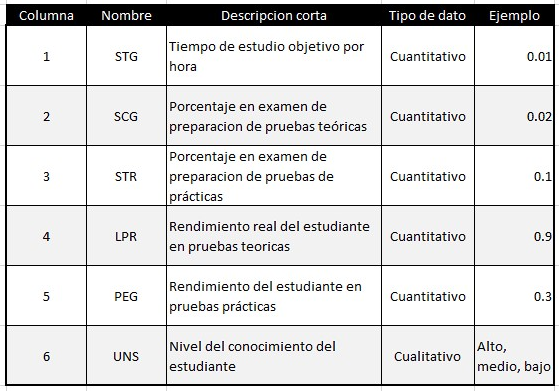

## --- Modificaciones previas a la importación del documento al espacio de trabajo

archivoxls = [saveTempPath, newName];
opts = detectImportOptions(archivoxls)

Error using detectImportOptions (line 381)
Unable to find or open 'D:\MATLAB_Drive_esc\TSISB_IA\practica_4\temp\escuela2.xlsx'. Check the path and filename or file permissions.

disp([opts.VariableNames' opts.VariableTypes'])
opts = setvaropts(opts,{'UNS'},'Type','categorical');
newValues = {'Tiempo','PorcentajeTeorico','PorcentajePractico','RendimientoTeorico','RendimientoPractico','Resultado'};
opts.VariableNames = newValues;
opts.SelectedVariableNames = {'RendimientoTeorico','RendimientoPractico','Resultado'};
opts.VariableNamingRule='preserve';
disp([opts.VariableNames' opts.VariableTypes'])

## --- Importacion a espacio de trabajo

dsEstudiante = readtable(archivoxls,opts);
head(dsEstudiante)

## --- Análisis exploratorio 1

%¿Cuantas categorias de valores tenemos como predictor?
valResultado = dsEstudiante.Resultado;
labels = categories(valResultado)
summary(valResultado)
close all
fig01 = figure;
hold on
    grid on
    histogram(valResultado,'BarWidth',0.5)
    xlabel("Rendimiento general del estudiante")
    ylabel("Promedio de muestras")    
hold off

## ---Análisis exploratorio 2

%¿Existe alguna relacion entre valores?
xvars = [...dsEstudiante.Tiempo,...
         ...dsEstudiante.PorcentajeTeorico,...
         ...dsEstudiante.PorcentajePractico,...
         dsEstudiante.RendimientoTeorico,...
         dsEstudiante.RendimientoPractico];
yvars = [...dsEstudiante.Tiempo,...
         ...dsEstudiante.PorcentajeTeorico,...
         ...dsEstudiante.PorcentajePractico,...
         dsEstudiante.RendimientoTeorico,...
         dsEstudiante.RendimientoPractico];

grp = dsEstudiante.Resultado;
grplabels={...'Tiempo',...
        ...'Porcentaje Teorico',...
        ...'Porcentaje Practico',...
        'Rendimiento Teorico',...
        'Rendimiento Practico'};
fig02 = figure;
hold on
    grid on
    [h,ax] = gplotmatrix(xvars,yvars,grp,colors,'.s^*',10)
    for i = 1:2
        xlabel(ax(2,i), grplabels{i})
        ylabel(ax(i,1), grplabels{i})
    end
hold off

# Aprendizaje Máquina supervisado

#### ***Segmentación de la informacion


tam = size(dsEstudiante,1);
PD = 0.3;
index = cvpartition(tam,'holdout',PD)
pTrain = dsEstudiante(index.training,:);
pTest = dsEstudiante(index.test,:);
size(pTrain)
size(pTest)

### ---Modelo de clasificacion de vecinos cercanos (KNN)

#### ***Entrenamiento del modelo

mdknn = fitcknn(pTrain,'Resultado');
preds = predict(mdknn,pTest);
err = loss(mdknn,pTest);
confusionchart(pTest.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(mdknn))
disp("Error de mala clasificacion: " + err*100 + "%")

#### ***Estandarizar los predictores

the software centers and scales each column of the predictor data ([`X`](https://www.mathworks.com/help/stats/fitcknn.html?s_tid=doc_ta#bt6cr9l-X)) by the column mean and standard deviation, respectively.

The software does not standardize categorical predictors, and throws an error if all predictors are categorical.

mdknn = fitcknn(pTrain,'Resultado','Standardize',false);
preds = predict(mdknn,pTest);
err = loss(mdknn,pTest);
confusionchart(pTest.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(mdknn))
disp("Error de mala clasificacion: " + err*100 + "%")

#### ***Modificacion de la distancia entre vecinos

Distance metric, specified as the comma-separated pair consisting of `'Distance'` and a valid distance metric name or function handle. 

mdknn = fitcknn(pTrain,'Resultado','Distance',"cityblock");
preds = predict(mdknn,pTest);
err = loss(mdknn,pTest);
confusionchart(pTest.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(mdknn))
disp("Error de mala clasificacion: " + err*100 + "%")

#### ***Numero de vecinos

Number of nearest neighbors in [`X`](https://www.mathworks.com/help/stats/fitcknn.html?s_tid=doc_ta#bt6cr9l-X) to find for classifying each point when predicting

mdknn = fitcknn(pTrain,'Resultado','NumNeighbors',4);
preds = predict(mdknn,pTest);
err = loss(mdknn,pTest);
confusionchart(pTest.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(mdknn))
disp("Error de mala clasificacion: " + err*100 + "%")

Mdl = fitcknn(pTrain,'Resultado','OptimizeHyperparameters','auto')
preds = predict(Mdl,pTest);
err = loss(Mdl,pTest);
confusionchart(pTest.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(Mdl))
disp("Error de mala clasificacion: " + err*100 + "%")

### ---Realizando predicciones con datos nuevos

#### ***Copiando archivos nuevos

%Nombre del archivo nuevo
prefix = ['\' 'noVistoEscuela2'];
sufix = '.xlsx';
newName2 = [prefix, sufix];

%Despues de correr esta celda por primera vez, crea un bloque de comentarios a partir de la siguiente linea
%{
%Interfaz de usuario
[fileName2, pathFileName2] = uigetfile('C:\','*.zip' );
fileOrigin2 = fullfile(pathFileName2,fileName2); %direccion de archivo elegido

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName2,fileName2)]);
    %Si solo quieres copiar
    [status, message, ~] = copyfile([pathFileName2,fileName2],[saveTempPath,newName2]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
    %----------------------

    %Si solo quieres extraer
    %zipExtraction = unzip(fileOrigin,fileDestination); 
    %fileZip = cell2mat(zipExtraction);
    %[status, message, ~] = copyfile(fileZip,[saveTempPath,newName]);
    %if status == 0
    %    disp(message)
    %else
    %    disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    %end
    %----------------------
end
%}

archivoxlsNuevo = [saveTempPath, newName2];
opts = detectImportOptions(archivoxlsNuevo);
disp([opts.VariableNames' opts.VariableTypes'])
opts = setvaropts(opts,{'UNS'},'Type','categorical');
newValues = {'RendimientoTeorico','RendimientoPractico','Resultado'};
opts.VariableNames = newValues;
opts.VariableNamingRule='preserve';
disp([opts.VariableNames' opts.VariableTypes'])
dsEstudianteNueva = readtable(archivoxlsNuevo,opts);
head(dsEstudianteNueva)
valResultado2 = dsEstudianteNueva.Resultado;
labels2 = categories(valResultado2)
summary(valResultado2)
disp([labels labels2])
dsEstudianteNueva.Resultado = renamecats(dsEstudianteNueva.Resultado,labels2,labels)
valResultado2 = dsEstudianteNueva.Resultado;
labels2 = categories(valResultado2);
isequal(labels, labels2)
disp([labels labels2])

### ---Predicciones sin hyperparametros

preds = predict(mdknn,dsEstudianteNueva);
err = loss(mdknn,dsEstudianteNueva);
confusionchart(dsEstudianteNueva.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(mdknn))
disp("Error de mala clasificacion: " + err*100 + "%")

### ---Predicciones CON hyperparametros

preds = predict(Mdl,pTest);
err = loss(Mdl,pTest);
confusionchart(pTest.Resultado,preds,"ColumnSummary","column-normalized")
disp("Training Error: " + resubLoss(Mdl))
disp("Error de mala clasificacion: " + err*100 + "%")

mdl = fitcnet(pTrain,"Resultado","LayerSize",5)